We set up the semidiscretization and initial condition in $x$ just as before.

m = 100;  [x,Dx,Dxx] = diffper(m,[0,1]);
u0 = exp( -60*(x-0.5).^2 );

Now, though, we apply `ode45` to the initial-value problem $\mathbf{u}'=\mathbf{D}_{xx}\mathbf{u}$.

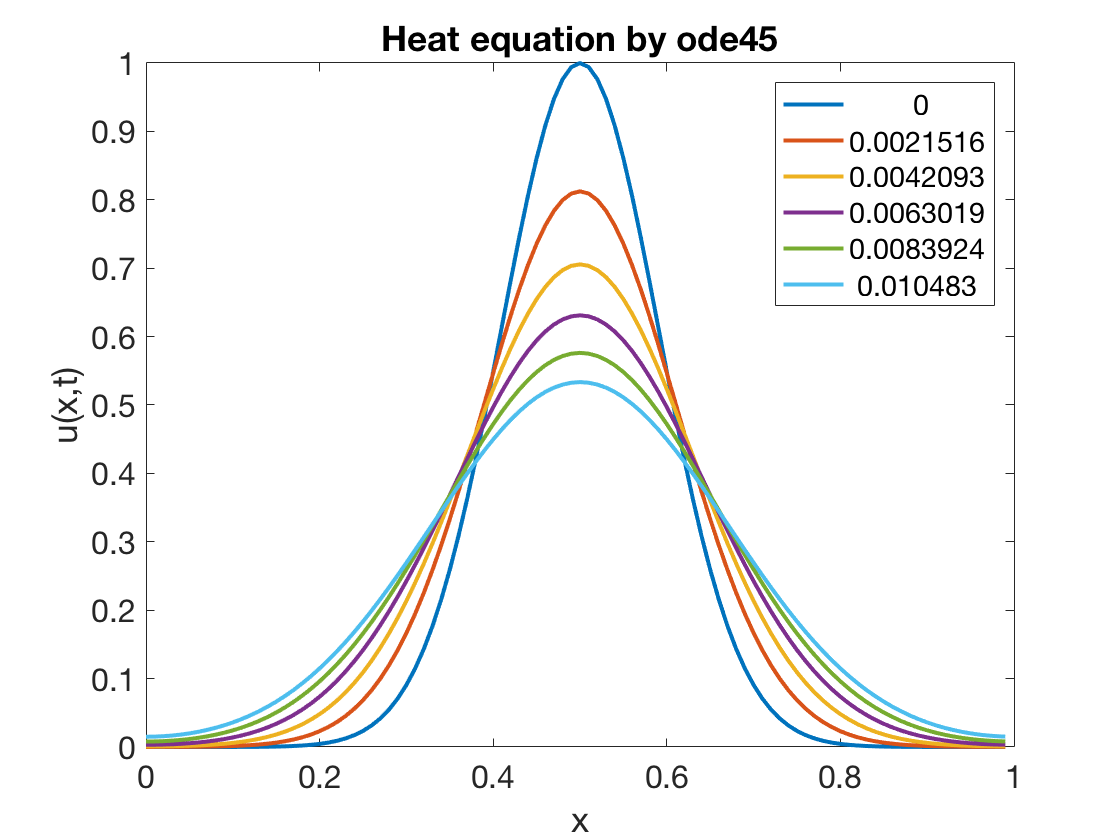

tfinal = 0.05;
ODE = @(t,u) Dxx*u;  
[t,U] = ode45(ODE,[0,tfinal],u0);
U = U';    % rows for space, columns for time
plot(x,U(:,1:100:501))
xlabel('x'), ylabel('u(x,t)')   % ignore this line
legend(num2str(t(1:100:501)))   % ignore this line
title('Heat equation by ode45')   % ignore this line

The solution is at least plausible. But the number of time steps that were selected automatically is surprisingly large, considering how smoothly the solution changes.

num_steps_ode45 = length(t)-1

num_steps_ode45 =     2404       


Now we apply another solver, `ode15s`. 

[t,U] = ode15s(ODE,[0,tfinal],u0);
U = U';    % rows for space, columns for time

The number of steps selected is reduced by a factor of more than 50!

num_steps_ode15s = length(t)-1

num_steps_ode15s =       41       
